# **EEE-3102: Numerical Technique Laboratory**

# **Lab-06: Determination of roots of a function by using Newton-Raphson method.**

#### Example-01:

Root of given function is 14.778528

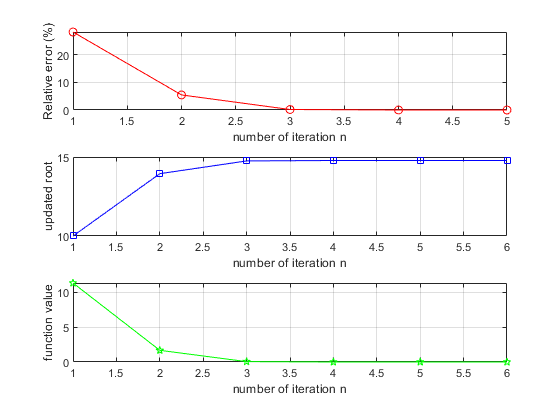

% Newton Raphson Method
clc;close all;clear all;
% Change here for different functions
f=@(x) x^3-x-1;
% this is the derivative of the above function
df=@(x) 3*x^2-1;
r=input ('please input the value of r : ');
tol=input('Percentage of relative error tolerance : ');
rel_error=1; % Error must be greater than tol
xr=r;
i=1;
% xri=xr;
while(rel_error>tol)
xr_old=xr;
xr=xr-(f(xr)/df(xr));
xrnew(i)=xr; %%%% xr updatecd after ithiteratiom
rel_error(i)=abs((xr-xr_old)/xr*100);
i=i+1;
end
fprintf('Root of given function is %f',xr)
n=1:1:i-1;
figure;
plot(n,rel_error,'-ro')
grid on
xlabel('number of iteration n')
ylabel('percentage of relative error')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
m=0:1:i-1;
xru=[r xrnew];
figure;
plot(m,xru,'-bs')
xlabel('number of iteration n')
ylabel('updated xr at each iteration')
grid on
f_xru=subs(f,xru);
figure;
plot(m,f_xru,'-gp')
xlabel('number of iteration n')
ylabel('function value for each updated xr')
grid on